# MECH 320 Finite Element Method Project

## Introduction

The finite element method isolates boundary conditions and initial value partial differential equations to solve complicated structural analysis, heat transfer, or fluid flow problems. The differential equation and boundary conditions are transformed into a large system of algebraic equations. This method utilizes a plethora of elements, requiring a computer to solve. 

Firstly, the differential equations are converted into integro-differential equations, which are applied at tiny elements of the main body connected by nodes. This process is called discretization and creates a mesh. The solution is found by applying the equations at each element and completely joining them all together to solve for the entire solid body.

The report describes the use of FEM to model a plate with a central hole and a plate with a central crack as shown below. The dispalcement magnitudes, von Mises stress and stress concentration factors are also calculated. 

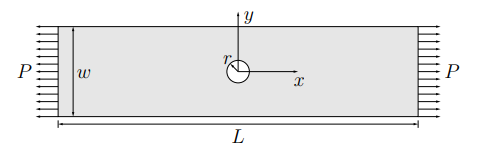

and this

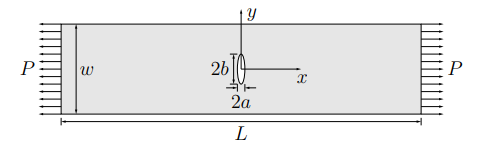

## Results

First we build the model to show the plate geometry and generated mesh

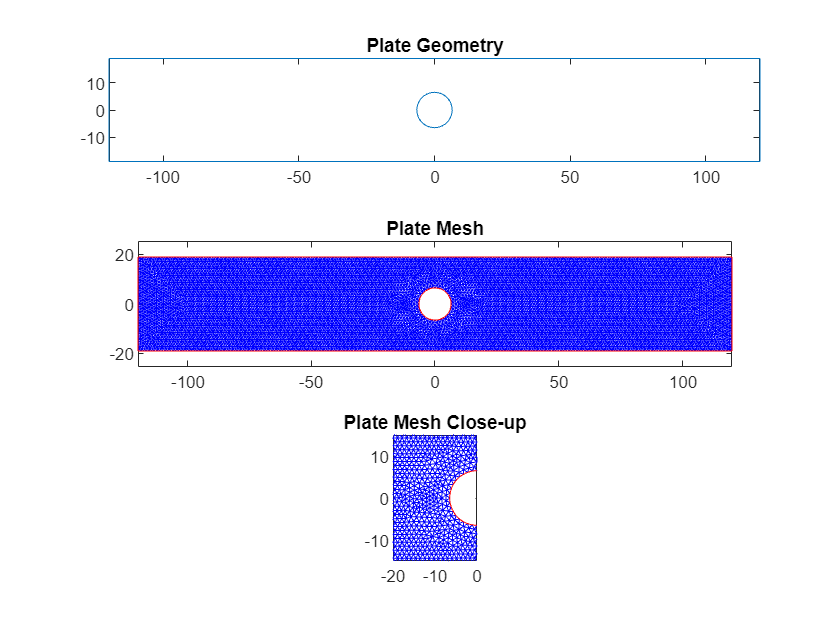

clc
clear all
close all

%% 1: Model parameters
half_crack_height = 6.5;       % Half crack height (mm)
half_crack_width = 1;        % Half crack width (mm)
half_width = 38/2;              % Plate half width (mm)
half_length = 240/2;             % Plate half length (mm)
youngs_modulus = 200*10^3;          % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;          % Poissons ration of material

surf_traction = 10;           % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [1 0 0 half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 4: Plotting

figure
tiledlayout(3,1)
% Geometry
nexttile          % Create figure
pdegplot(model); % Plot model geometry
axis equal       % Set equal scales for x and y axes
title('Plate Geometry');    % Plot title

% Mesh
nexttile
pdemesh(model); % Plot model mesh
axis equal    % Set equal scales for x and y axes
title('Plate Mesh');   % Plot title

%Mesh Close up
nexttile
pdemesh(model); % Plot model mesh
xlim([-20 0]);
ylim([-15 15]);
title('Plate Mesh Close-up');   % Plot title

Then we find the stress and displacement distribution created by the applied load P

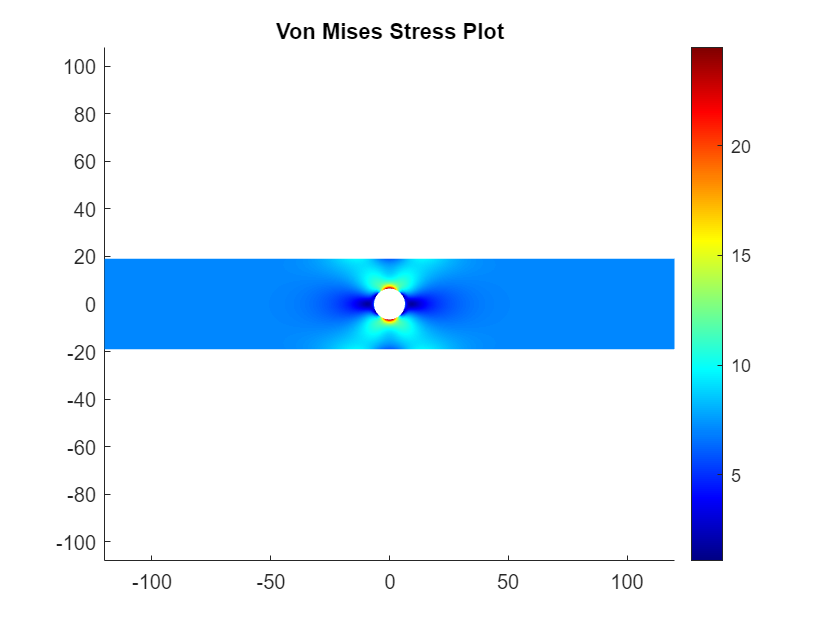

% Von Mises stress contours
svon = 0.5.*sqrt((sol.Stress.sxx-sol.Stress.syy).^2+(0-sol.Stress.sxx).^2+6*(sol.Stress.sxy).^2);   % Calculate von Mises stress

figure                                         % Create figure
pdeplot(model,'XYData',svon,'ColorMap','jet'); % Plot xy data (in this case the von Mises stress)
axis equal                                     % Set equal scales for x and y axes
title('Von Mises Stress Plot');                     % Plot title

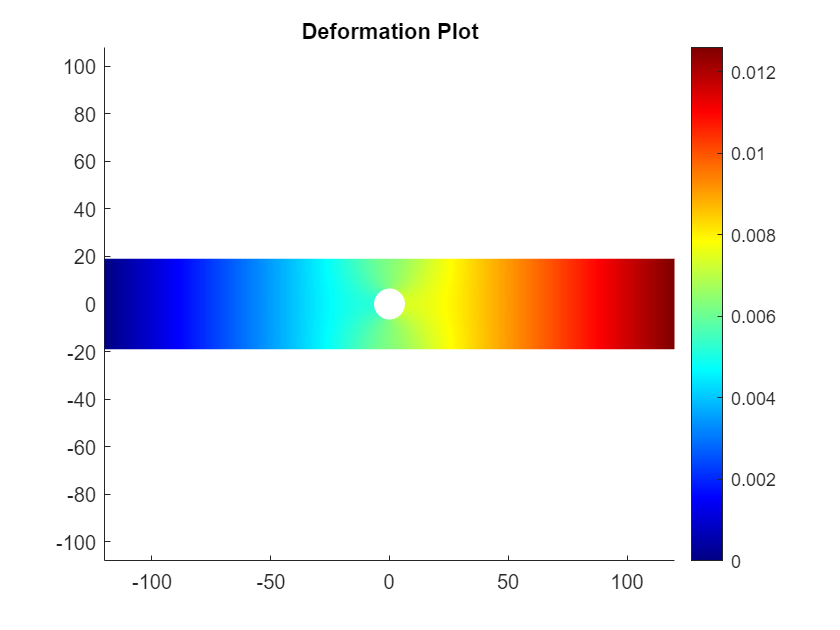


% Deformed shape
figure                                         % Create figure
pdeplot(model,"XYData",sol.Displacement.x,"Deformation",sol.Displacement,"DeformationScaleFactor",plot_scale_factor,"ColorMap","jet"); % Plot xy data (in this case displacement and deformation superimposed)
axis equal                                     % Set equal scales for x and y axes
title('Deformation Plot');                    % Plot title

The stress concentration factor is defined as follows for a bar with a hole:


$$\sigma_{\max } =K\sigma_o =K\;\frac{F}{A}=K\;\frac{P\;t}{\left(w-2a\right)t}=K\;\frac{P}{\left(w-2a\right)}$$


We can solve for the stress concentration factor in terms of values obtained through the problem definition and the model


$$K=\sigma_{\max } \frac{\left(w-2a\right)}{P}$$


We can use theoretical method employed in the Photoelasticity lab to find the theoretical nominal and max stresses. Both calculations are shown below.

%% 5: Calculate stress concentration factor

p = [-100,0];                         % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx; % Nominal stress x obtained at point far away from hole

smax = max(sol.Stress.sxx)  ;      % Maximum normal stress x in the plate
k_fem = smax/snom;
r = half_crack_width;
theta = pi/2;
snom_thoery = surf_traction/(2*half_width); 
s_r = 0.5*snom_thoery*((1+3-4)*cos(2*theta)); %radial stress at top of hole
s_theta = 0.5*snom_thoery*((1+1)-(1+3)*cos(2*theta)); %tangential stress at top of hole
t_rtheta = -0.5*snom_thoery*(1-3+2)*sin(2*theta); %shear stress at top of hole

smax_theory = s_r*cos(theta)^2+s_theta*sin(theta)^2-2*t_rtheta*sin(theta)*cos(theta);

k_theory = smax_theory/snom_thoery;

%photo elasticity data from 162.75N applied to bar with hole
snom_photo = 0.75; %photoelasticy nominal stress [MPa]
smax_photo = 3.04; %photoelasticy max stress [MPa] ie. stress at edge of hole

k_photo = smax_photo/snom_photo;

fprintf("k_model = %d\nk_theory=%d\nk_photo=%d\n",k_fem,k_theory,k_photo);               % Print k to the console

k_model = 3.480600e+00
k_theory=3
k_photo=4.053333e+00


Now increase the width to 240 mm and create the mesh:

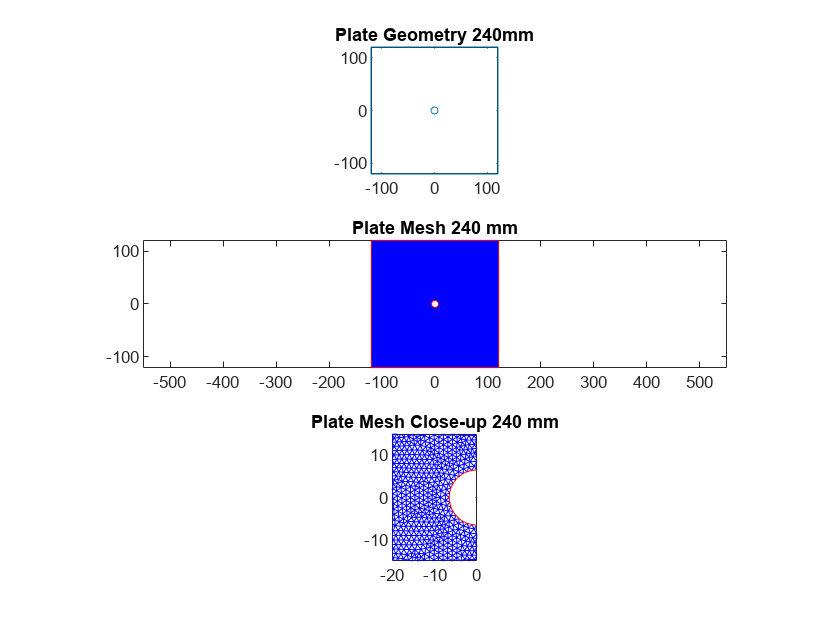

%% 5: Calculate stress concentration factor
half_width2 = 240/2;                        % new half width of geometry

surf_traction = 10;           % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% New Vector representing rectangular plate geometry
plate2 = [3 4 -half_length half_length half_length -half_length -half_width2 -half_width2 half_width2 half_width2]';

% Vector representing circular or elliptical hole geometry
hole = [1 0 0 half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate2, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model2 = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model2,geom);

% Specify material properties
structuralProperties(model2,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model2,'Edge',3,'XDisplacement',0);
structuralBC(model2,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model2,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model2,'Hmax',mesh_size);

% Solve system of equations
sol2 = solve(model2);

%% 4: Plotting

figure
tiledlayout(3,1)
% Geometry
nexttile          % Create figure
pdegplot(model2); % Plot model geometry
axis equal       % Set equal scales for x and y axes
title('Plate Geometry 240mm');    % Plot title

% Mesh
nexttile
pdemesh(model2); % Plot model mesh
axis equal    % Set equal scales for x and y axes
title('Plate Mesh 240 mm');   % Plot title

%Mesh Close up
nexttile
pdemesh(model2); % Plot model mesh
xlim([-20 0]);
ylim([-15 15]);
title('Plate Mesh Close-up 240 mm');   % Plot title

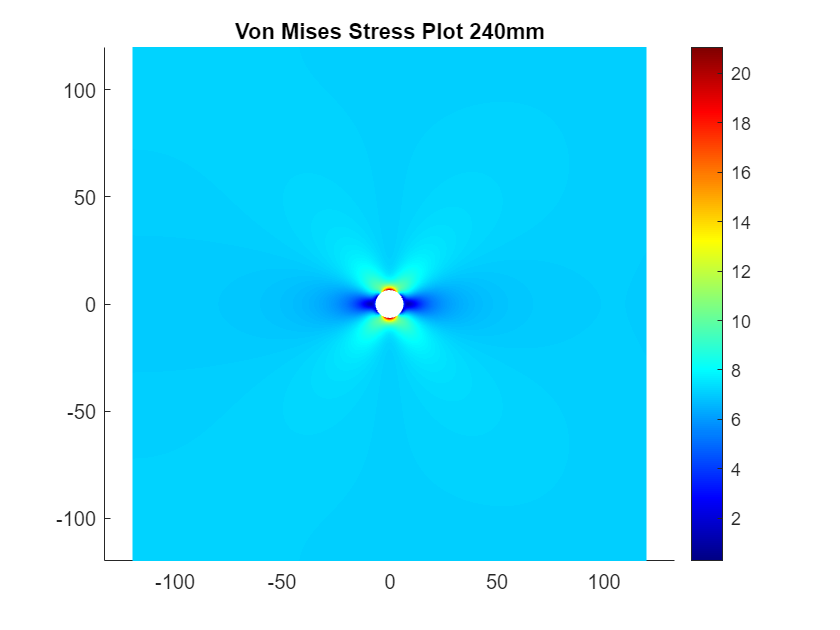



% Von Mises stress contours
svon2 = 0.5.*sqrt((sol2.Stress.sxx-sol2.Stress.syy).^2+(0-sol2.Stress.sxx).^2+6*(sol2.Stress.sxy).^2);   % Calculate von Mises stress

figure                                         % Create figure
pdeplot(model2,'XYData',svon2,'ColorMap','jet'); % Plot xy data (in this case the von Mises stress)
axis equal                                     % Set equal scales for x and y axes
title('Von Mises Stress Plot 240mm');                     % Plot title

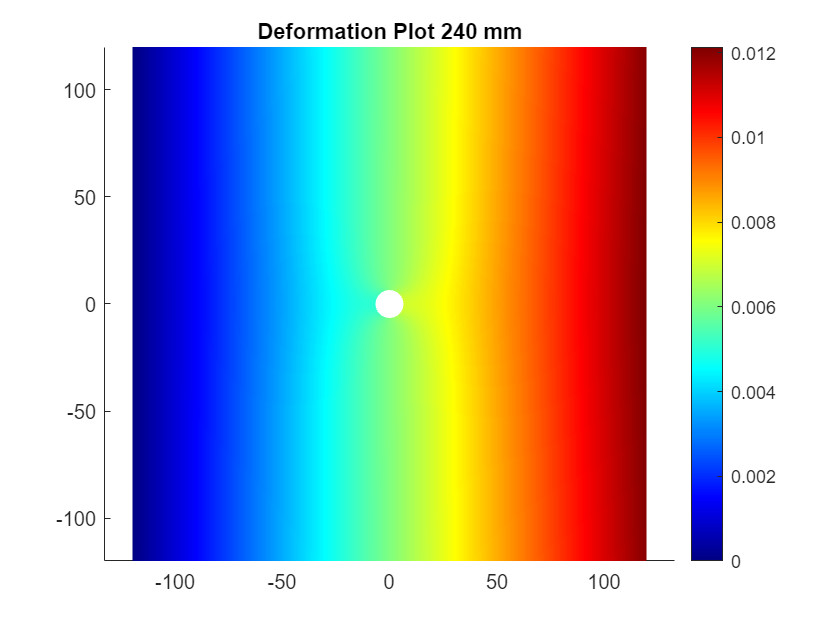


% Deformed shape
figure                                         % Create figure
pdeplot(model2,"XYData",sol2.Displacement.x,"Deformation",sol2.Displacement,"DeformationScaleFactor",plot_scale_factor,"ColorMap","jet"); % Plot xy data (in this case displacement and deformation superimposed)
axis equal                                     % Set equal scales for x and y axes
title('Deformation Plot 240 mm');                    % Plot title

Find stress and displacement and then calculate K:

The stress concentration factor is defined as follows for a bar with a hole:


$$\sigma_{\max } =K\sigma_o =K\;\frac{F}{A}=K\;\frac{P\;t}{\left(w-2a\right)t}=K\;\frac{P}{\left(w-2a\right)}$$


We can solve for the stress concentration factor in terms of values obtained through the problem definition and the model


$$K=\sigma_{\max } \frac{\left(w-2a\right)}{P}$$


We can use theoretical method employed in the Photoelasticity lab to find the theoretical nominal and max stresses. Both calculations are shown below.

% Von Mises stress contours
svon2 = 0.5.*sqrt((sol2.Stress.sxx-sol2.Stress.syy).^2+(0-sol2.Stress.sxx).^2+6*(sol2.Stress.sxy).^2);   % Calculate von Mises stress

%% 5: Calculate stress concentration factor

p = [-100,0];                         % Coordinates of point far away from the hole
snom2 = interpolateStress(sol2,p').xx; % Nominal stress x obtained at point far away from hole

smax2 = max(sol2.Stress.sxx)  ;      % Maximum normal stress x in the plate
k_fem2 = smax2/snom2;
r = half_crack_width;
theta = pi/2;
snom_thoery2 = surf_traction/(2*half_width2); 
s_r2 = 0.5*snom_thoery2*((1+3-4)*cos(2*theta)); %radial stress at top of hole
s_theta2 = 0.5*snom_thoery2*((1+1)-(1+3)*cos(2*theta)); %tangential stress at top of hole
t_rtheta2 = -0.5*snom_thoery2*(1-3+2)*sin(2*theta); %shear stress at top of hole

smax_theory2 = s_r2*cos(theta)^2+s_theta2*sin(theta)^2-2*t_rtheta2*sin(theta)*cos(theta);

k_theory2 = smax_theory2/snom_thoery2;


fprintf("k_model(240mm) = %d\nk_theory(240mm)=%d\n",k_fem2,k_theory2);% Print k to the console

k_model(240mm) = 3.031069e+00
k_theory(240mm)=3


### Eliptical Hole

Similarly, the stress distribution and displacement magnitudes can be calculated for an eliptical hole with the dimensions shown below.

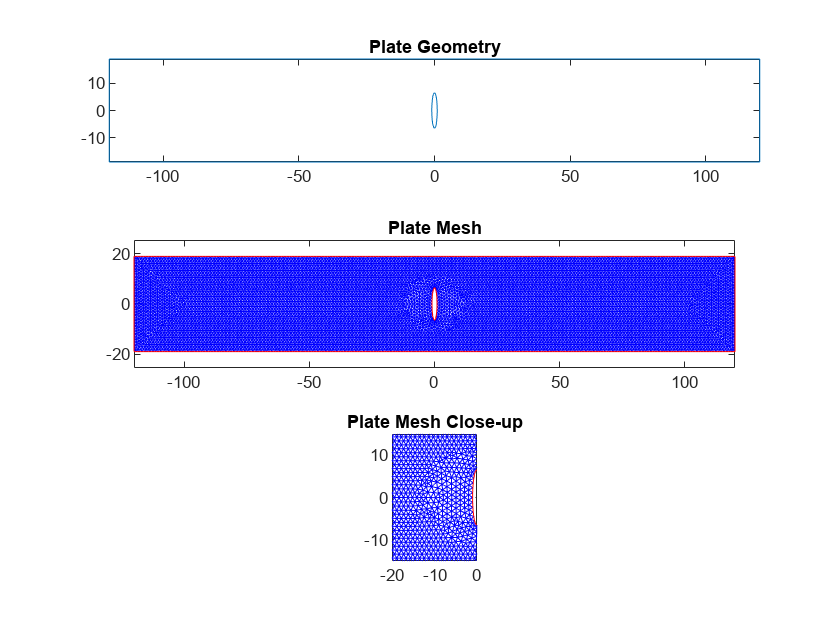

clc

%% 1: Model parameters
half_crack_height = 6.5;     % Half crack height (mm)
half_crack_width = 1;        % Half crack width (mm)
half_width = 38/2;           % Plate half width (mm)
half_length = 240/2;         % Plate half length (mm)
youngs_modulus = 200*10^3;   % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;        % Poissons ration of material

surf_traction = 10;              % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [4 0 0 half_crack_width half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 4: Plotting

figure
tiledlayout(3,1)
% Geometry
nexttile          % Create figure
pdegplot(model); % Plot model geometry
axis equal       % Set equal scales for x and y axes
title('Plate Geometry');    % Plot title

% Mesh
nexttile
pdemesh(model); % Plot model mesh
axis equal    % Set equal scales for x and y axes
title('Plate Mesh');   % Plot title

%Mesh Close up
nexttile
pdemesh(model); % Plot model mesh
xlim([-20 0]);
ylim([-15 15]);
title('Plate Mesh Close-up');   % Plot title

Again, select the stresses and compute the Von Mises stress distribution, and the deformed shape of the bar.

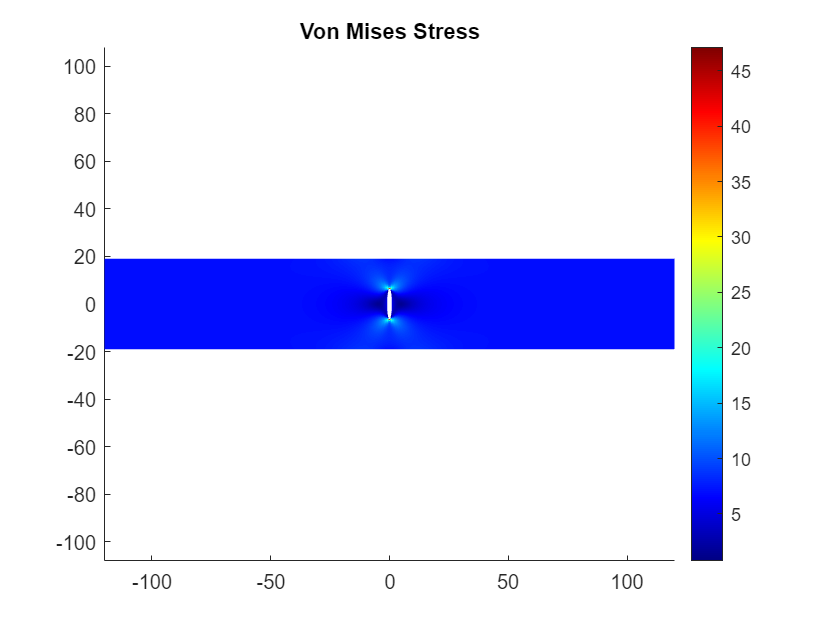

% Von Mises stress contours
svon = 0.5.*sqrt((sol.Stress.sxx-sol.Stress.syy).^2+(0-sol.Stress.sxx).^2+6*(sol.Stress.sxy).^2);   % Calculate von Mises stress

figure                                         % Create figure
pdeplot(model,'XYData',svon,'ColorMap','jet'); % Plot xy data (in this case the von Mises stress)
axis equal                                     % Set equal scales for x and y axes
title('Von Mises Stress');                     % Plot title

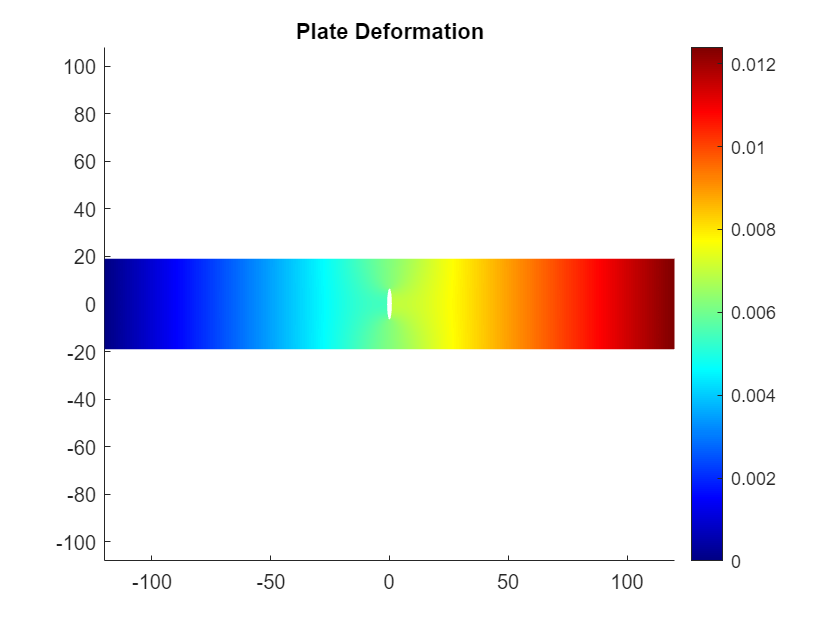


% Deformed shape
figure                                         % Create figure
pdeplot(model,"XYData",sol.Displacement.x,"Deformation",sol.Displacement,"DeformationScaleFactor",plot_scale_factor,"ColorMap","jet"); % Plot xy data (in this case displacement and deformation superimposed)
axis equal                                     % Set equal scales for x and y axes
title('Plate Deformation');                    % Plot title

Finally, the stress concentration factor is computed and compared with the theoretical value. This time however, the theoretical stress concentration factor is computed using the formula provided in the lab manual:


$$K=1+2\left( \frac{a}{b} \right)$$
 

where $a$ and $b$ are the half minor and half major axis of the elipse respectively.

%% 5: Calculate stress concentration factor
p = [-100,0];                                   % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx;            % Nominal stress x obtained at point far away from hole
smax = max(sol.Stress.sxx);                     % Maximum normal stress x in the plate
k_theory = 1+2*(half_crack_height/half_crack_width);   % Stress concentration factor for ellipse
k_fem    = smax/snom;
fprintf("snom = %d\nsmax = %d\nk_theory = %d\nk_fem = %d\n", snom, smax, k_theory, k_fem);

snom = 1.000003e+01
smax = 7.751193e+01
k_theory = 14
k_fem = 7.751166e+00


This exact procedure is repeated for an ellipse with $a=3$ and $a=6$ to compare stress concentration factors. First, $a=3$:

clc

%% 1: Model parameters
half_crack_height = 6.5;     % Half crack height (mm)
half_crack_width = 3;        % Half crack width (mm)
half_width = 38/2;           % Plate half width (mm)
half_length = 240/2;         % Plate half length (mm)
youngs_modulus = 200*10^3;   % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;        % Poissons ration of material

surf_traction = 10;              % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [4 0 0 half_crack_width half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 5: Calculate stress concentration factor
p = [-100,0];                                   % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx;            % Nominal stress x obtained at point far away from hole
smax = max(sol.Stress.sxx);                     % Maximum normal stress x in the plate
k_theory = 1+2*(half_crack_height/half_crack_width);   % Stress concentration factor for ellipse
k_fem    = smax/snom;
fprintf("snom = %d\nsmax = %d\nk_theory = %d\nk_fem = %d\n", snom, smax, k_theory, k_fem);

snom = 1.000007e+01
smax = 5.605128e+01
k_theory = 5.333333e+00
k_fem = 5.605090e+00


Finally $a=6$:

clc
%% 1: Model parameters
half_crack_height = 6.5;     % Half crack height (mm)
half_crack_width = 6;        % Half crack width (mm)
half_width = 38/2;           % Plate half width (mm)
half_length = 240/2;         % Plate half length (mm)
youngs_modulus = 200*10^3;   % Youngs Modulus of material (MPa)
poissons_ratio = 0.3;        % Poissons ration of material

surf_traction = 10;              % Surface traction (N/mm)
mesh_size = half_crack_height/6; % Mesh refinement (no need to change)

plot_scale_factor = 1;       % Scale factor for plotting deformations, adjust it to be able to visualize contraction of the plate near the hole


% Vector representing rectangular plate geometry
plate = [3 4 -half_length half_length half_length -half_length -half_width -half_width half_width half_width]';

% Vector representing circular or elliptical hole geometry
hole = [4 0 0 half_crack_width half_crack_height]';
hole = [hole;zeros(length(plate)-length(hole),1)];

% Define geometry description matrix (GDM) as a subtraction operation between hole and bar
gdm = [plate, hole];                   % Form the GDM containing all the shapes
names = char('bar','hole')';          % Give names to shapes
geom = decsg(gdm,'bar - hole',names); % Boolean subtraction of hole from bar

%% 3: FEM model (no need to modify this section)
model = createpde('structural','static-planestress');

% Create geometry and include it into the structural model
geometryFromEdges(model,geom);

% Specify material properties
structuralProperties(model,'YoungsModulus',youngs_modulus,'PoissonsRatio',poissons_ratio);

% Apply boundary conditions
structuralBC(model,'Edge',3,'XDisplacement',0);
structuralBC(model,'Vertex',3,'YDisplacement',0);
structuralBoundaryLoad(model,'Edge',1,'SurfaceTraction',[surf_traction;0]);

% Generate mesh
generateMesh(model,'Hmax',mesh_size);

% Solve system of equations
sol = solve(model);

%% 5: Calculate stress concentration factor
p = [-100,0];                                   % Coordinates of point far away from the hole
snom = interpolateStress(sol,p').xx;            % Nominal stress x obtained at point far away from hole
smax = max(sol.Stress.sxx);                     % Maximum normal stress x in the plate
k_theory = 1+2*(half_crack_height/half_crack_width);   % Stress concentration factor for ellipse
k_fem    = smax/snom;
fprintf("snom = %d\nsmax = %d\nk_theory = %d\nk_fem = %d\n", snom, smax, k_theory, k_fem);

snom = 1.000014e+01
smax = 3.641877e+01
k_theory = 3.166667e+00
k_fem = 3.641827e+00


## Discussion of Results

For the first geometry, the stress concentration value K was calculated to be 3.4806. In the photoelasticity lab, the K value found was 4.0533. These are close but not entirely accurate. Considering the vast difference in the way they were calculated, this is not surprising. Small factors during the photoelasticity lab can easily manipulate the value. Considering the theoretical value was 3, the finite element anaylsis is seemingly more accurate.

The geometry plot, mesh plot, close-up plot, von Mises, and deformation plot for the plate can be found in the output section of this Live Script (side-by-side their respective code).

With the recalculation of K values using a width of 240 mm, the K value found by the FEM was 3.031, extremely close to the theoretical 3. Since the new plate is larger with the same mesh calculation, it has a greater number of finite elements. Since the FEM becomes more accurate depending on the number of finite elements used in the calulation, the larger plate will yield more accurate results. This also shows why FEMs are completed by computers and not humans: the number of calculations needed for accuracy is much better suited to a computer.

The plots for the new plate (with width at 240 mm) can be found in the output section below the original plate.

A plot of the plate is first created with a width of 38mm and length of 240mm. The half height of the crack was defined as 6.5mm and the half width was 1mm. The model plate was then generated along with the mesh as shown below. 

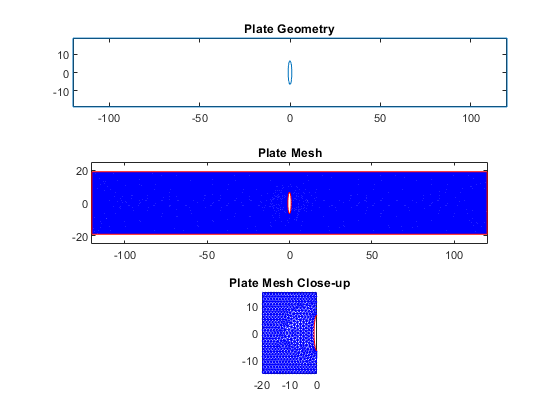

*Figure X. Plate Geometry and generated mesh for a plate with a crack*

The von Mises stress distribution is then represented by solving the stress distributin and mapping the von Mises values. The corresponding displacement magnitudes are also shown. 

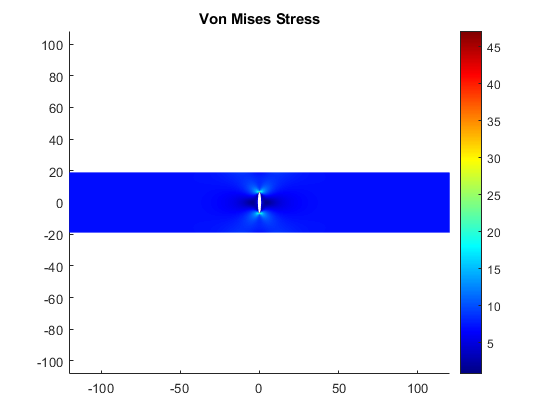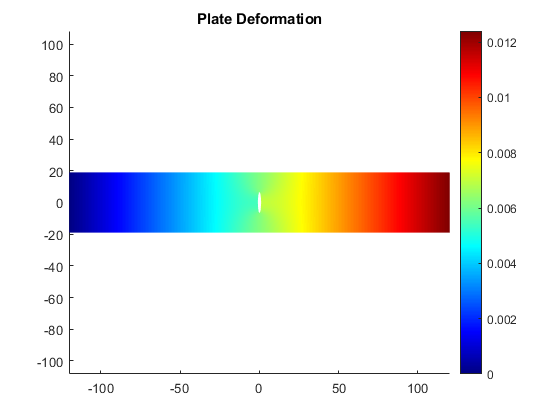

*Figure X. Von Mises stress and Deformation for a plate with a crack *

The stress intensity factor is calculated using the equation shown below where $a$ and $b$ are the half minor and half major axis of the elipse respectively.


$$K=1+2\left( \frac{a}{b} \right)$$
 

The calculated theoretical value was found to be 14 while the FEM resulted in 7.75. When compared to the circle with a = 1mm, a significant variation is found. The variation can be accounted for by understanding that K is the ratio of maximum stress to nominal stress. The larger maximum stress experienced by the ellipse for the same nominal stress results in a larger stress concentration factor. 

When the half width of the crack is increased to 3mm, the theoretical stress concentration decreases to 5.33 and the FEM stress concentraton decreases to 5.609. The values decreases further when the half width of the crack is set to 6mm with the theoretical and FEM K values being 3.16 and 3.64 respectively. The increasing accuracy of the FEM model can clearly be attributed to the increase in crack width. This is due to the mesh size being related to the crack height which is fixed throughout the calculations. A very small feature such as a 1mm crack is dififcult to model accurately as the relative number of elements is lower for such small geometries. When the crack size is increased the number of elements in contact with the crack also increases which results in more accurate results. This relationship shows a clear limitation of the FEM method and the importance of using multiple techniques to verify results. 

## Concluding Remarks

The report detailed the succesful usage of the FEM methodology to model a plate with a crack and a plate with a hole while under axial tension. The von Mises stress distribution and plate deformation were also calculated for each geometry and represented graphically using a color map. The stress concentration factor for the plate with a hole was found to be relatively accurate when compared with the photoelastic method and thoeretical calculations. The stress concentration factor found using FEM for the plate with an elliptical hole in it was initially innacurate when compared to the thoeretical value. However, with increasing crack width the accuracy of the FEM model improved due to the larger number of elements on the feature.The project clearly demonstrated the practiality and potential limitations of using FEM. 

## References